# IEM Tutorial: fundamentals

First, let's go over a first set of basic concepts underlying the IEM method, ignoring the overhead associated with data processing. I've simplified a dataset into one number from each measurement (electrode) on each trial.

In this tutorial, we'll use this dataset to learn:

- how to build a channel-based linear encoding model

- how to use that encoding model, together with a behavioral task, to predict how modeled channels should respond

- how to compute the contribution of each channel to each measurement (here, activity from EEG electrode or each fMRI voxel)

- how to *invert* that estimated *encoding model* to solve for channel responses on a separate set of data

- how to think about these reconstructions

The EEG data we're using is a single subject from the beautiful dataset generously shared online (https://osf.io/bwzfj/) by Joshua Foster in the Awh/Vogel labs at University of Chicago (https://awhvogellab.com). This dataset comes from his 2016 *Journal of Neurophysiology* paper (https://awhvogellab.files.wordpress.com/2015/08/foster-et-al-2016_jneurophysiol.pdf), in which they recorded EEG while participants remembered single positions on the screen over a brief delay interval. Here's a schematic of the task (their **Fig. 1**):

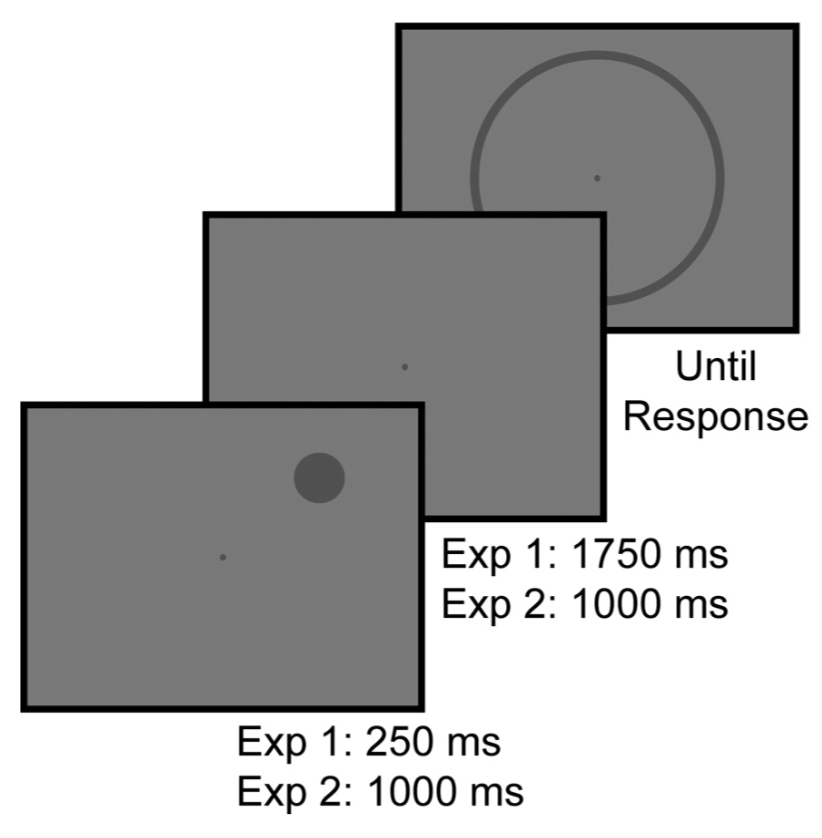

If you're using **EEG data**, we're going to use data from one participant (participant 10 in the online dataset) in Experiment 1. For this first tutorial, we're going to use a simplified dataset in which I've already extracted 'mean delay period activity' in each electrode on each trial (alpha band power). In the advanced tutorial, we'll also do this step ourselves. 

On each trial, the remembered position was drawn from a fully uniform distribution around a circle (no variation in eccentricity). The variable `c_all `tells us the polar angle of the remembered position on each trial, and the 'bin' (of 8) to which it belongs in columns 1, and 2, respectively.

If you're using **fMRI data**, we're going to use data from one participant of an unpublished study conducted at NYU which is very similar to the EEG study described above (participants remembered a position in spatial working memory over an extended delay interval; 12,000 ms for fMRI). Data included is extracted from bilateral visual area V3AB, which is a dorsal stream region which strongly represents attended and remembered information. I've extracted the mean delay period response for each voxel from 5.25-12 s after the target was presented.

First, let's take a look at the data.

## Load data

I've already minimally-processed this dataset so that we have a measured scalp activity pattern (alpha) on each trial. We'll cover ways to get this pattern later on. In principle, the data could have been from an fMRI experiment - the point is that any signal can be a good candidate for this analysis, so long as some of the assumptions (discussed below) more or less hold. 

addpath util/ % this is where some helper functions live

which_data = 'fMRI'; % 'EEG' or 'fMRI'

% load the data
load(sprintf('../data/%s/%s_fundamentals.mat',which_data,which_data)); 
whos

  Name                Size               Bytes  Class     Attributes

  c_all             192x2                 3072  double              
  data_all          192x779            1196544  double              
  delay_window        1x2                   16  double              
  excl_all          192x1                 1536  double              
  r_all             192x1                 1536  double              
  which_data          1x4                    8  char                



in your workspace, you should have:

- **data_all**: one activity pattern on each trial from each measurement (electrode) - n_trials x n_measurements

- **c_all**: condition label for each trial. first column is the polar angle remembered on that trial, in degrees (Cartesian coords, 45 = upper right); second column is the position bin (1-8; beginning at 0 deg and moving CCW, so bin 2 is centered at 45, 3 at 90, etc); n_trials x 2

- **excl_all**: logical vector, contains 1 for each trial that was marked by Foster et al (2016) for exclusion based on artifacts, etc; n_trials x 1 (for EEG; for fMRI, all zeros)

- **r_all**: label for each trial as to which run it came from; n_trials x 1

- **chan_labels** (for EEG): cell array of strings labeling each electrode; n_electrodes+2 x 1 cell array (we don't include EOG channels in data here)

if using EEG data,` filter_band` tells us the frequencies used for computing power during the delay period:

if strcmpi(which_data,'EEG') % no filtering applied for fMRI
    filter_band
end

And, `delay_window` tells us which time points are extracted (ms):

delay_window

delay_window =         5250       12000


This is all we need! we'll go over a few suggestions for how to process EEG data for best use with IEM methods a bit later.

## STEP 1: Build encoding model

The central assumption in the IEM analysis framework is that we can model the activity of an aggregate neural measurement (EEG electrode; fMRI voxel) as a linear combination of a discrete set of modeled 'information channels', which we sometimes call 'basis functions'. For now, let's think of those information channels as a set of neural populations - we know, based on decades of vision science, that neural populations in the visual system are *tuned* to particular features. 

What are some examples of these?

- orientation

- motion

- spatial position <-- we'll focus on this one, since it's easiest

- color

A very important part of the IEM approach is to build SIMPLIFIED models - we know that spatial RFs in visual cortex tile the whole visual field, from fovea to periphery, etc. But do we need to model all known aspects of these neural populations? Especially for something like EEG, NO. We need to model the *relevant dimensions* for our task. In the datasets we're working with, stimuli were always presented along a ring at equal eccentricity - so we can only measure changes in neural responses as a function of polar angle - there is no point in trying to model different responses for different stimulus eccentrificites, since we never measured that! (see Sprague & Serences, 2013; 2014; 2016 for examples of this analysis across eccentricity as well)

The point is: *THE MODEL SHOULD REFLECT YOUR UNDERSTANDING OF NEURAL SENSITIVITY PROFILES AND THE CONSTRAINTS OF YOUR EXPERIMENTAL DESIGN*

At an extreme level: consider modeling sensitivity to color (e.g., Brouwer & Heeger, 2009) for the datasets we're using here. The stimuli we used never spanned that dimension, so such modeling is futile! We'll see below some of the mathematical/theoretical constraints on these models.  

Ok - back to modeling. Here's a rough schematic of what we're doing:

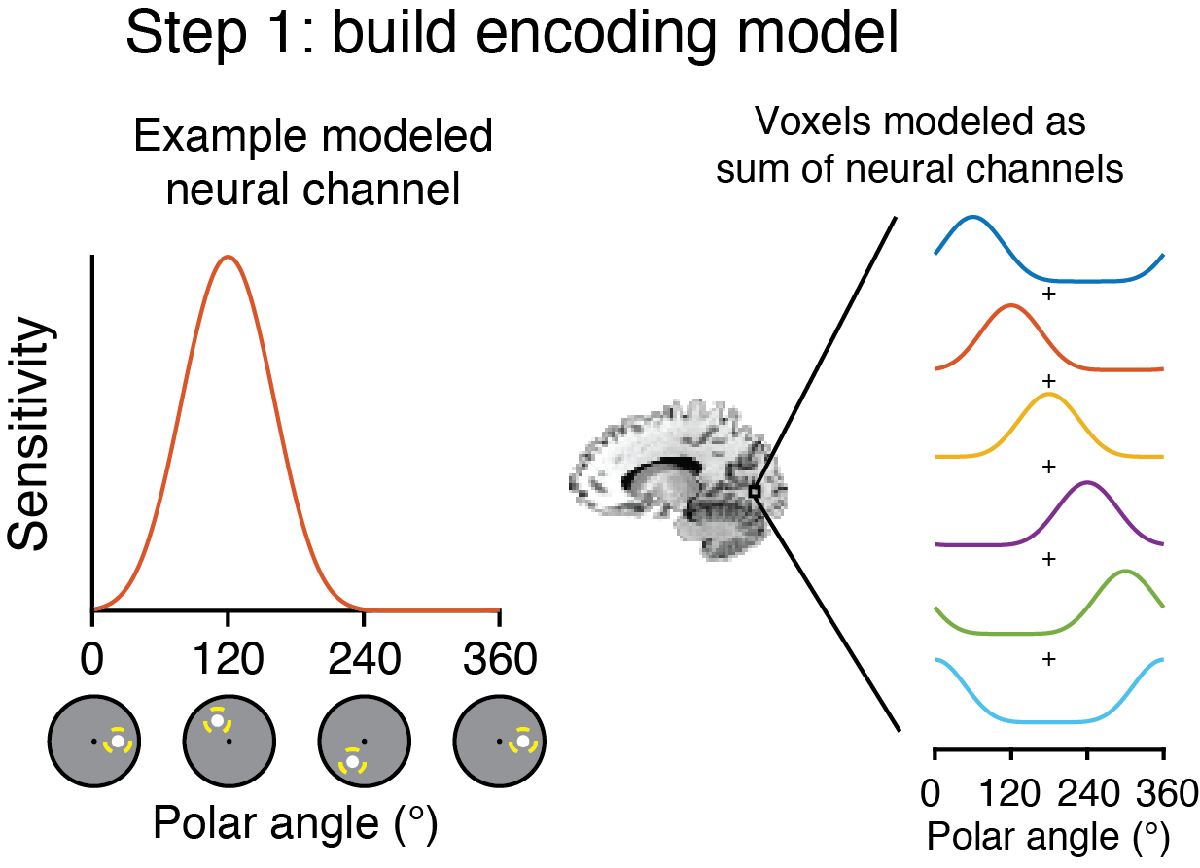

The IEM framework we're using in this tutorial is LINEAR: that means, for each electrode, we're making the direct assumption that


$$B=W_1 C_1 +W_2 C_2 +\cdots +W_n C_n$$


Where $B$ is measured activity on each trial, $C_i$ is the activity of the i'th modeled information channel on that trial, and $W_i$ is the *weight *describing how strongly channel $C_i$ contributes to the electrode in question.

So - let's look at an example 'channel' profile. We want to model a channel as a linear filter for the relevant feature value (position), similar to a neural tuning function or receptive field. Since stimuli varied only in their position around the circle, we'll model this channel as a function of polar angle, $f\left(\theta \right)$, such that the channel is maximally sensitive at a particular feature value (polar angle), and insensitive at far away feature values. A Gaussian could do the trick, but a Gaussian will never reach 'zero' sensitivity - so instead we use cos functions raised to a power to make them a bit more gaussian-like:


$$f_0 \left(\theta \right)=\cos {\left(\pi \frac{\left(\theta -\theta_0 \right)}{2s}\right)}^7 \;\textrm{where}\;\left|\theta \right|<s,0\;\textrm{otherwise}$$


This lets us know exactly the position where the function reaches zero (s), which can be helpful. But, in practice, using a Gaussian (normalized to 1) is equally useful. 

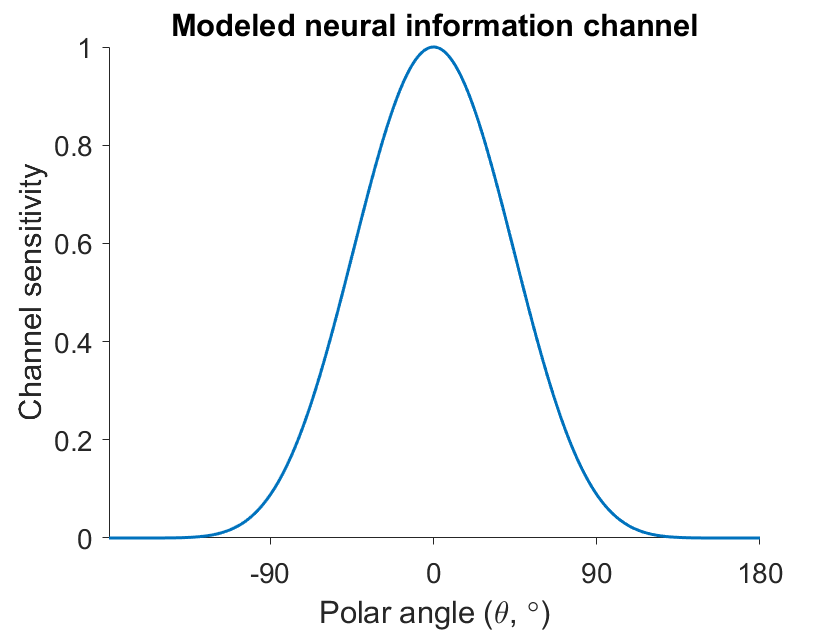

% define a set of points along which we evaluate the channel function
angs = linspace(-179,180,360);

% define where the channel is centered (deg)
this_chan_center = 0; 

% define how wide the channel is - how far from its center does it reach 0
% (it will reach nearly 0 much closer to its center)
this_chan_width = 180; 

% quick uitility function to compute angular distance (degrees):
ang_dist = @(a,b) min(mod(a-b,360),mod(b-a,360));

% the above function will make it easy to always compute the distance between two angles, with the max value being 180

% use our equation above to compute the channel sensitivity profile (its filter shape)
this_basis_fcn = (cosd(180 * ang_dist(angs,this_chan_center) ./ (2*this_chan_width) ).^7) .* (ang_dist(angs,this_chan_center)<=this_chan_width);

% and let's take a look at it:
plot(angs,this_basis_fcn,'-','LineWidth',1.5);
xlabel('Polar angle (\theta, \circ)');
ylabel('Channel sensitivity'); xlim([angs(1) angs(end)])
title('Modeled neural information channel')
set(gca,'FontSize',14,'TickDir','out','box','off','XTick',-180:90:180)

Try changing things like the width of the channel (`this_chan_width`) and its center location (`this_chan_center`) - it's important to notice that the channel exists in a circular space, so that when it's centered at, say, 180 deg, it peaks again on the opposite side of the space. You can try plotting it in polar coordinates too:

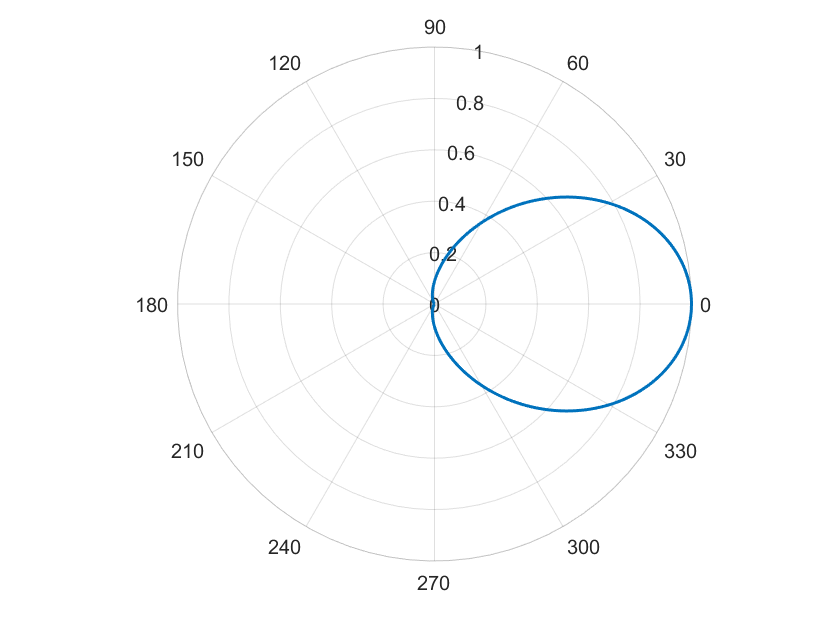

polarplot(deg2rad(angs),this_basis_fcn,'-','LineWidth',1.5);

This modeled neural information channel, tells us how we think some arbitrary population of neurons in the brain responds to a visual stimulus (spatial location). For today's purposes, we're treating channels as linear filters - the channel responds as a weighted sum of its 'input' (mask of stimulus location). Today we'll only be considering a single stimulus modeled as a point, so the shape of the channel response can be thought of as the response to each possible stimulus value around the screen.

But, we also don't think the brain cares only about a single position. So, we need our channels to tile the feature space - here, polar angle. So let's make a set of `n_chans` basis functions, which model the sensitivity of each channel. We call this a ***basis set***, because we assume that the observed activity in each electrode is a sum of the activity of these modeled channels. This is similar to the use of a series of sine waves as the basis set of a periodic signal in frequency-domain analyses.

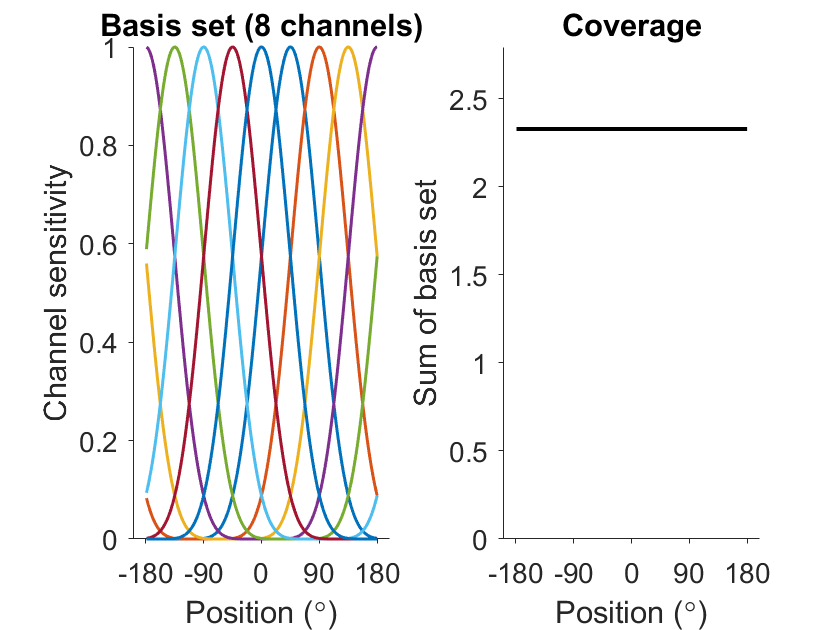

% can adjust these to see how differences in basis set change results below
n_chans = 8;       % DEFAULT: 8
chan_width = 180;  % DEFAULT: 180
chan_centers = linspace(360/n_chans,360,n_chans);

% let's write a function to create our basis function:
build_basis = @(eval_at,this_center,this_width) (cosd(180 * ang_dist(eval_at,this_center) ./ (2*this_width) ).^7) .* (ang_dist(eval_at,this_center)<=this_width);

% and let's build the basis set - all of our channels tuned to different positions
basis_set = nan(length(angs),n_chans);
for bb = 1:n_chans
    basis_set(:,bb) = build_basis(angs,chan_centers(bb),chan_width);
end

% plot the whole basis set
figure; subplot(1,2,1);
plot(angs,basis_set,'-','LineWidth',1.5);
xlabel('Position (\circ)'); ylabel('Channel sensitivity');
title(sprintf('Basis set (%i channels)',n_chans));
set(gca,'XTick',-180:90:180,'TickDir','out','Box','off','FontSize',14);

% and plot the sum of all channels - this tells us if there are any 'holes' in the coverage
subplot(1,2,2);
plot(angs,sum(basis_set,2),'k-','LineWidth',2);
xlabel('Position (\circ)'); ylabel('Sum of basis set');
title('Coverage');
set(gca,'XTick',-180:90:180,'TickDir','out','Box','off','FontSize',14);
tmpylim = get(gca,'YLim'); ylim([0 1.2*tmpylim(2)]); clear tmpylim;

## STEP 2a: Use encoding model to predict channel responses

We now have our full encoding model in-hand (and try playing w/ those parameters and re-running analyses). Remember, we haven't touched data yet! This is purely an exercise in a computer at this point - we've built a model for how a neural population might respond to a particular feature of a visual stimulus (position), and then built a 'basis set' of several of those modeled neural populations. This is all under the assumption that the measured neural responses from EEG/fMRI in an electrode/voxel will be made up of this basis set: in the same way a periodic signal is made up of sines/cosines, the signal in our aggregate measurements is thought to be made up of activity in neural populations modeled by these basis functions.

Now, we need to use our encoding model to predict how each modeled population should respond on each trial of the experiment. (note that you don't actually need data for this step either!). We do this by computing a 'stimulus mask' - a vector describing the stimulus in feature space. Because our feature space is polar angle, the vector for each trial will mark the position of the stimulus in polar angle. Let's start with an example trial. 

Remember that '`c_all`' contains the polar angle of each trial in its first column.

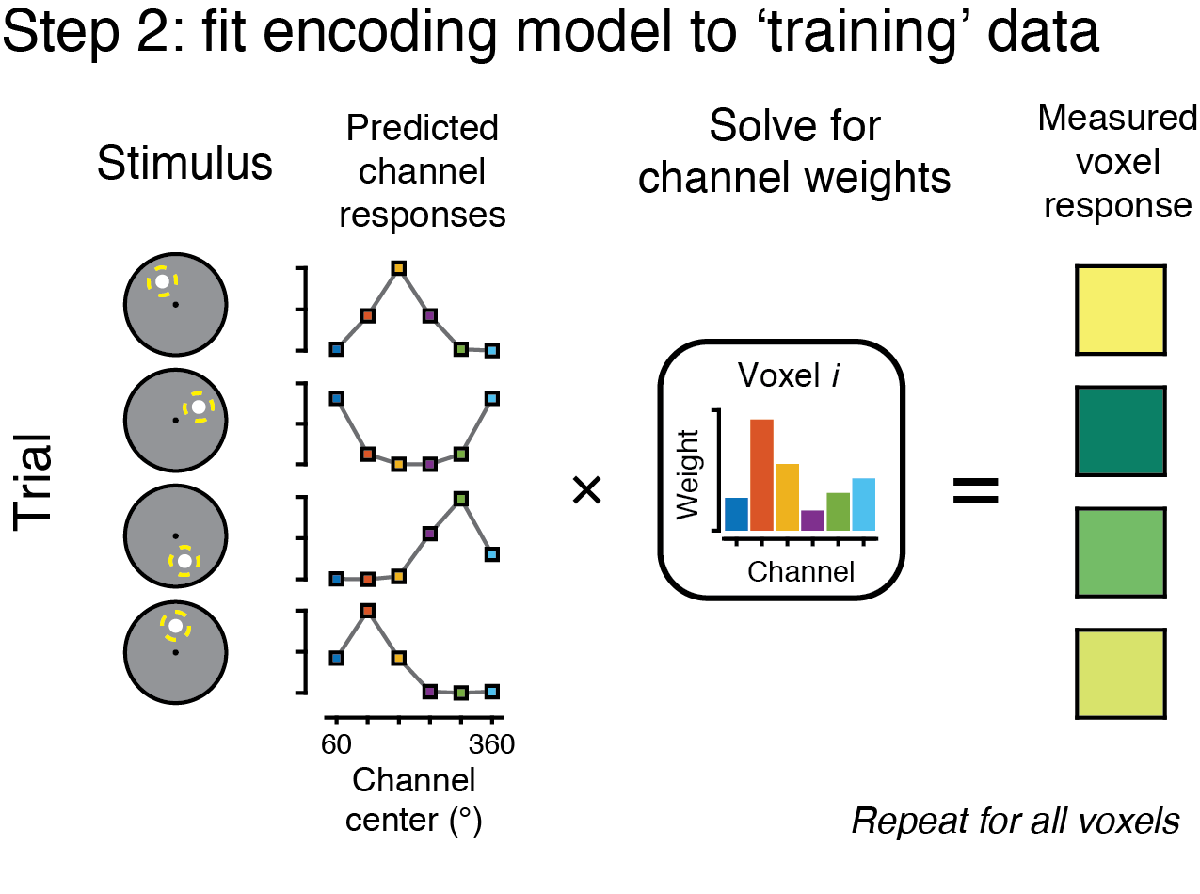

% quick: let's fix c_all(:,1) to be from -180:180:
c_all(c_all(:,1)>180,1) = c_all(c_all(:,1)>180,1)-360;
which_trial = 1;
c_all(which_trial,1)

ans = 118

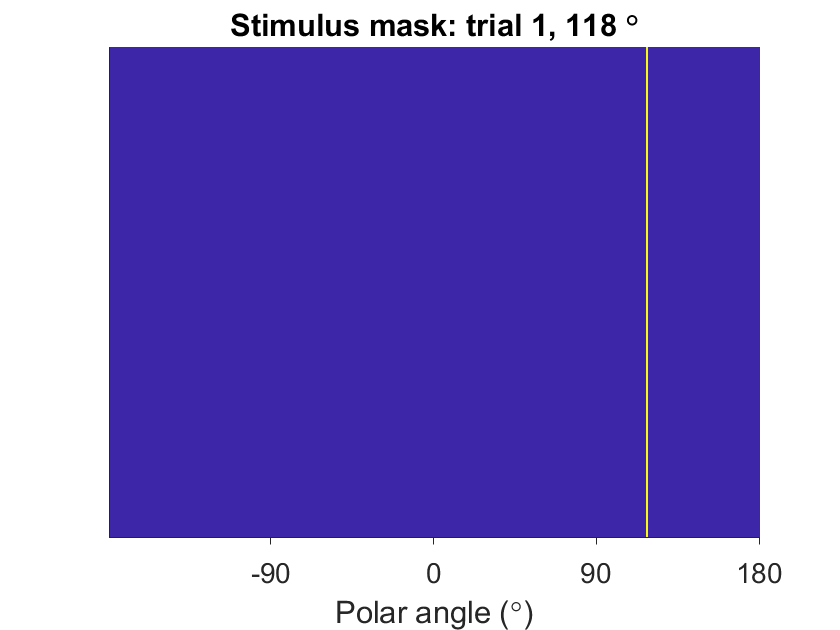

% initialize a blank mask
this_mask = zeros(length(angs),1);

% fill in the mask with a '1' at the feature value for this trial
this_mask(angs==c_all(which_trial,1))=1;

% plot the mask as an image
figure;imagesc(angs,1,this_mask.'); 
xlabel('Polar angle (\circ)');
set(gca,'XTick',-180:90:180,'TickDir','out','YTick',[],'Box','off','FontSize',14);
title(sprintf('Stimulus mask: trial %i, %i \\circ',which_trial,c_all(which_trial,1)));

Easy enough - we could, if we wanted, compute the stimulus mask in different ways: we could assume the representation is a fuzzy blob, or a wide strpe, etc. But, it's easier for now to just assume a single 'perfect' feature value. The stimulus mask is important, though, as it is used to predict channel responses, and so changes in the choice of mask can (subtly) impact results. 

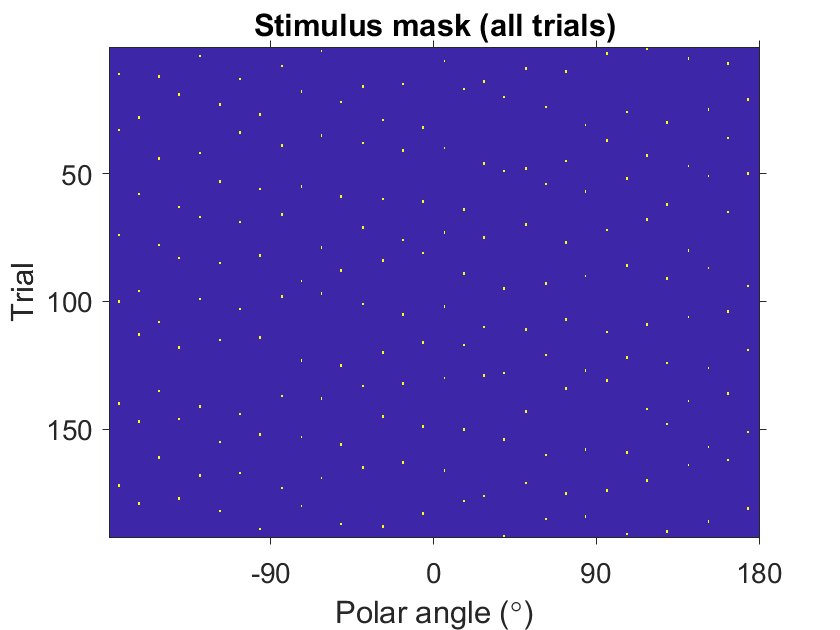

% make stimulus mask for all trials: do the same thing within a loop over trials
stim_mask = zeros(size(c_all,1),length(angs));
for tt = 1:size(c_all,1)
    stim_mask(tt,angs==c_all(tt,1)) = 1;    
end

% plot it - now we have a mask of the stimulus value on each trial
figure;
imagesc(angs,1:size(c_all,1),stim_mask); axis ij;
ylabel('Trial')
xlabel('Polar angle (\circ)');
set(gca,'TickDir','out','FontSize',14,'XTick',-180:90:180);
title('Stimulus mask (all trials)')

Next, let's use our stimulus mask (n_trials x n_angs) and our basis set (n_angs x n_chans) to predict channel responses. 

We want one number for each channel for each trial - let's store it as a matrix called $\mathit{\mathbf{C}}$that's n_trials x n_chans. Because the predicted channel response for each channel is just the weighted sum of the stimulus mask by the channel sensitivity profile (basis_set), we can pretty easily compute $\mathit{\mathbf{C}}$with matrix math. If $\mathit{\mathbf{S}}$is the stimulus mask and $\mathit{\mathbf{F}}$is the basis set (with dims above), we can do: $\mathit{\mathbf{C}}=\mathit{\mathbf{SF}}$

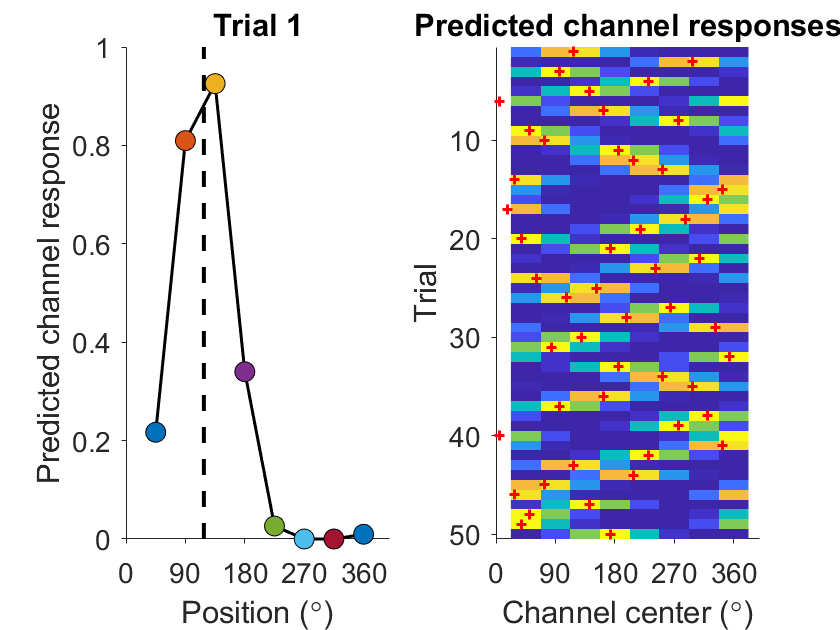

% I'm going to be verbose with variable names, but we often call pred_chan_resp X (convention for regression desgin matrix) or C (in the math descriptions of IEM in papers)
pred_chan_resp = stim_mask * basis_set;

% let's plot an example trial (as above) and the full predicted channel response matrix
figure;
subplot(1,2,1); 
chan_colors = lines(n_chans);
hold on;
plot(chan_centers,pred_chan_resp(which_trial,:),'k-','LineWidth',1.5);
for cc = 1:n_chans
    plot(chan_centers(cc),pred_chan_resp(which_trial,cc),'ko','MarkerSize',10,'MarkerFaceColor',chan_colors(cc,:))
end
plot([1 1]*mod(c_all(which_trial),360),[0 1],'k--','LineWidth',2);

title(sprintf('Trial %i',which_trial));
xlabel('Position (\circ)'); ylabel('Predicted channel response');
set(gca,'TickDir','out','FontSize',14,'XTick',0:90:360);
hold off;

subplot(1,2,2); hold on;
imagesc(chan_centers,1:size(pred_chan_resp,1),pred_chan_resp);
% add a red + on each trial showing the feature value
plot(mod(c_all(:,1),360),1:size(c_all,1),'r+','LineWidth',1.5,'MarkerSize',5);
axis ij;
xlabel('Channel center (\circ)');
title('Predicted channel responses');
ylabel('Trial');
ylim([1 50]+[-.5 0.5]); % zoom in on a subset of trials
set(gca,'TickDir','out','FontSize',14,'XTick',0:90:360);
hold off;

Try changing properties of the basis set and seeing how predicted channel responses change. You should notice that wider basis functions (channels) result in a 'wider' predicted channel response function - that is, more correlated predicted channel responses. That can cause some issues later, and we'll see that below. 

## STEP 2b: Use predicted channel responses to fit encoding model

As described above, the central premise of the IEM approach we're using here is that the activity of each signal (electrode) is a combination of the activity of a discrete set of modeled channels. For a single measurement $B$, that looks like:


$$B=W_1 C_1 +W_2 C_2 +\cdots +W_n C_n$$


You might recognize this as a linear regression problem - we know $B$ - the activity in an electrode on each trial - and $C$ - the predicted response of each channel on each trial - and we want to solve for $W$. We can do this most simply with matrix math. We rewrite this as:


$$\mathit{\mathbf{B}}=\mathit{\mathbf{C}}\;\mathit{\mathbf{W}}$$


Where B is n_trials x 1, C is n_trials x n_chans, and W is n_chans x 1.

To solve for $\mathit{\mathbf{W}}$, we need to multiply $\mathit{\mathbf{B}}$ on the left by the inverse of $\mathit{\mathbf{C}}$. But $\mathit{\mathbf{C}}$isn't square! That's ok - it's common in matrix math to use the Moore-Penrose pseudo-inverse to perform matrix divisioin:


$$\hat{\mathit{\mathbf{W}}} ={\left({\mathit{\mathbf{C}}}^T \mathit{\mathbf{C}}\right)}^{-1} {\mathit{\mathbf{C}}}^T \;\mathit{\mathbf{B}}$$


In  MATLAB:

which_meas = 7; % which electrode or voxel we're looking at
this_data = data_all(:,which_meas); % NOTE: we're including bad trials right now!!! (and no CV)
this_w = inv( pred_chan_resp.' * pred_chan_resp ) * pred_chan_resp.' * this_data;

However, for this to work, there are some constraints on $\mathit{\mathbf{C}}$: 

- To compute a unique solution for $\mathit{\mathbf{W}}$, it's necessary for the predicted responses for each channel to be sufficiently different (as an extreme example, if the predicted responses for two channels were always identical, it's impossible to decide which weight to assign each of them). When might this happen?

- There must be at least n_chans unique sets of predicted channel responses; this typically means there must be n_chans or more unique stimuli which result in unique predicted channel responses. 

- If both of these requirements are fulfilled, your $\mathit{\mathbf{C}}$matrix will be 'full-rank' - it will have rank equal to the number of columns (the rank of the matrix is the number of linearly-independent columns; if rank < n_cols, one column can be expressed as a combination of the others, and so its impossible to uniquely estimate a solution for $\mathit{\mathbf{W}}$)

Let's check our $\mathit{\mathbf{C}}$:

rank(pred_chan_resp)

ans = 8

(We'd have seen errors or warnings in MATLAB if our $\mathit{\mathbf{C}}$wasn't full-rank - but this is *always* something important to keep track of!)

## Brief aside: restrictions on encoding models

Because this experiment involved a full uniform distribution of positions, it's actually pretty challenging to adjust the basis set to parameters that result in rank-deficient $C$. But, we can illustrate a quick example if we instead predict channel responses based on the stimulus position bin (0, 45, 90, etc). This will result in only 8 unique predicted channel response patterns. Under what conditions would we expect to see a rank-deficient predicted channel response ($\mathit{\mathbf{C}}$) matrix? 

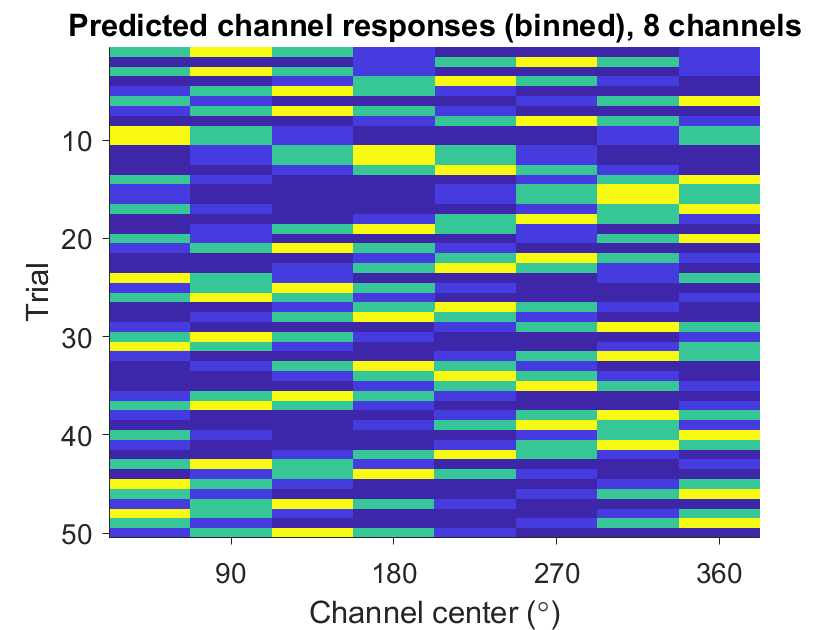

% need to make a new stimulus mask, and a temporary set of basis functions for testing this
stim_mask_bin = zeros(size(c_all,1),length(angs));
bin_centers = linspace(0,315,8); % the bin centers
bin_centers(bin_centers>180) = bin_centers(bin_centers>180)-360;
for tt = 1:size(c_all,1)
    stim_mask_bin(tt,angs==bin_centers(c_all(tt,2))) = 1;
end

n_chans_bin = 8; % try adjusting this
chan_centers_bin = linspace(360/n_chans_bin,360,n_chans_bin);
chan_width_bin = 180; % and this

basis_set_bin = nan(length(angs),n_chans_bin);

for bb = 1:n_chans_bin
    basis_set_bin(:,bb) = build_basis(angs,chan_centers_bin(bb),chan_width_bin);
end

% predict channel responses:
pred_chan_resp_bin = stim_mask_bin * basis_set_bin;

% plot predicted channel responses
figure;
imagesc(chan_centers_bin,1:size(c_all,1),pred_chan_resp_bin);
xlabel('Channel center (\circ)'); ylabel ('Trial'); title(sprintf('Predicted channel responses (binned), %i channels',n_chans_bin));
ylim([1 50] + [-0.5 0.5])
set(gca,'XTick',0:90:360,'TickDir','out','FontSize',14,'Box','off')

% Check the rank:
rank(pred_chan_resp_bin)

ans = 8

Under what scenarios does the rank not equal the number of channels? 

What if you can only acquire a very small number of trials - what does that do to the number of channels that can be independently estimated?

## Back to business: fitting models across all voxels

Ok - now that we've learned how to check to be sure we've built a 'good' and 'fittable' model, we can move on. 

Above we fit an encoding model to a single measurement (single EEG electrode). This is a *univariate *operation - meaning we can fit each measurement individually and get the same answer as if we fit to all measurements at the same time. The encoding model's job is to describe activity in a measurement, and that requires no information about other measurements. So, we can fit the encoding model to all measurements very easily using the same linear algebra, just a bigger data matrix:


% fit to data_all, not this_data
this_w_all = inv( pred_chan_resp.' * pred_chan_resp ) * pred_chan_resp.' * data_all;

% NOTE: MATLAB suggests we switch to backslash notation, which gives an identical result:
% this_w_all_backslash = pred_chan_resp \ data_all;


## STEP 3: Reconstructing channel responses

So far, we've learned how to design an encoding model, and how to fit it to a set of data. This encoding model describes how a modeled set of neural information channels contribute to each measurement. 

Now, we're going to put that model to work. Our model - $\hat{\mathit{\mathbf{W}}}$ - describes the relationship between our data - $\mathit{\mathbf{B}}$ - and our predicted channel responses on each trial - $\mathit{\mathbf{C}}$- under our linear model:


$$\mathit{\mathbf{B}}=\mathit{\mathbf{C}}\mathit{\mathbf{W}}\;$$


Our goal with this analysis is to recover the channel responses most likely to give rise to an observed activation pattern - ${\mathit{\mathbf{B}}}_{\mathrm{new}}$. 

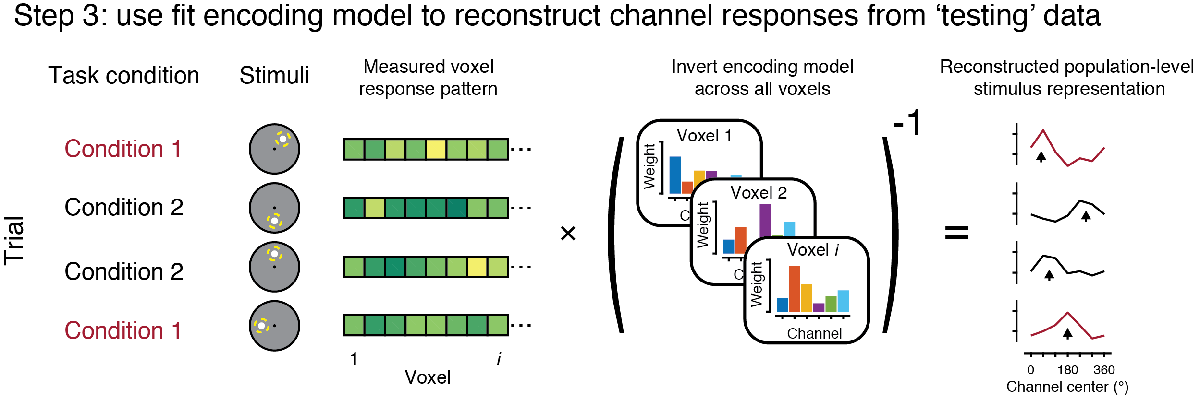

Because we know $\hat{\mathit{\mathbf{W}}}$and we know ${\mathit{\mathbf{B}}}_{\textrm{new}}$, we can just solve for ${\mathit{\mathbf{C}}}_{\mathbf{new}}$:


$${\mathit{\mathbf{C}}}_{\textrm{new}} ={{\mathit{\mathbf{B}}}_{\textrm{new}} {\hat{\mathit{\mathbf{W}}} }^T \left(\hat{\mathit{\mathbf{W}}} \;\hat{{\mathit{\mathbf{W}}}^{\mathit{\mathbf{T}}} } \right)\;}^{-1}$$


Because of our linear assumptions this is an easy problem to solve - we just need to ***INVERT*** our ***ENCODING MODEL*** ($\hat{\mathit{\mathbf{W}}}$)! Let's look at an example, we'll take ~50% of trials, randomly chosen, as data used to estimate the model & use the remaining data to reconstruct:

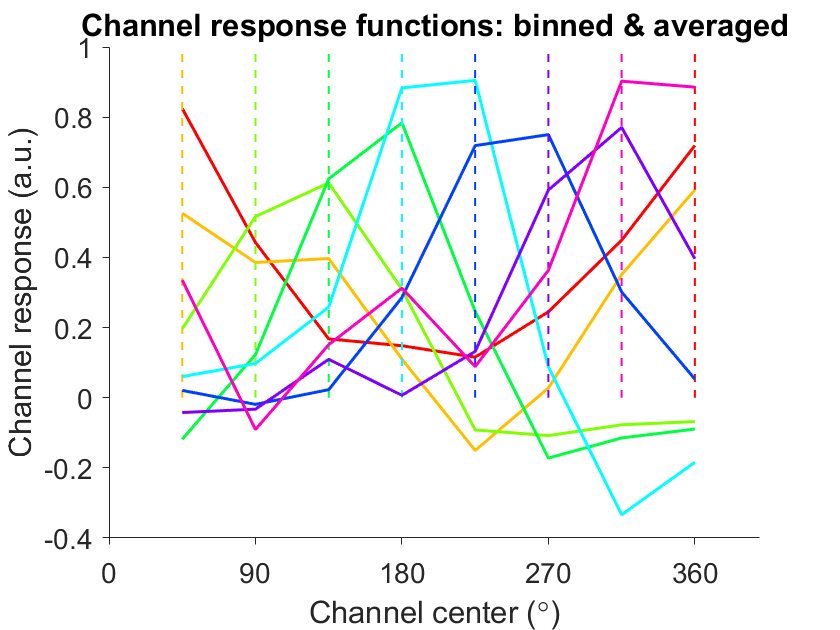


rng(3728291); % so we get the same answer everytime
tmprnd = rand(size(c_all,1),1);
trn_proportion = 0.5; 

% select trn_proportion of trials to train with (but don't keep excluded trials)
trnidx = tmprnd <= trn_proportion & ~excl_all;

% for the test data, pick the complement:
tstidx = tmprnd > trn_proportion & ~excl_all;

% estimate encoding model using 'training' trials
trn = data_all(trnidx,:);
trnX = pred_chan_resp(trnidx,:); % because pred_chan_resp is a 'design matrix' in a linear model, it's often called 'X'

this_W = trnX \ trn;  % estimate W

% use W to compute channel responses:
tst = data_all(tstidx,:);

% this is where we *invert* the encoding model (IEM)! it's where the name comes from!
this_chan_resp = tst * this_W.' * inv(this_W * this_W.'); % estimated channel responses on each trial!
% above is equivalently written as: this_chan_resp = tst/this_W - we'll use this format later on!


% plot average reconstructions for each position bin
figure; hold on;
% get a variable we can use to index into position bins
pu = unique(c_all(:,2));
this_c = c_all(tstidx,:); % label for each trial

% colors for plotting
pos_colors = hsv(length(pu));
bin_centers_plot = mod(bin_centers,360); bin_centers_plot(bin_centers_plot==0)=360;
for pp = 1:length(pu)
    
    % pick the trials in this bin
    thisidx = this_c(:,2)==pu(pp); 
    
    % plot channel responses
    plot(chan_centers,mean(this_chan_resp(thisidx,:),1),'-','LineWidth',1.5,'Color',pos_colors(pp,:));
    
    % plot position bin center - this should match the 'peak' of the reconstruction
    plot(bin_centers_plot(pp)*[1 1],[0 1],'--','LineWidth',1,'Color',pos_colors(pp,:));
end
xlabel('Channel center (\circ)');
ylabel('Channel response (a.u.)');
title('Channel response functions: binned & averaged')
set(gca,'TickDir','out','FontSize',14,'XTick',0:90:360);
hold off;

Ok - let's recap what we just did. 

First, we divided data into **training** and **test** sets (or model-estimation and reconstruction sets). Next, we estimated the encoding model ($\hat{\mathit{\mathbf{W}}}$) using the training set. Then, we *inverted* that encoding model to compute channel responses, given that encoding model, during each trial in the held-out test set of data. This step, whereby we *invert* the encoding model, is where the magic happens. This is the first (and only) step where we're using *multivariate* information across all measurements (electrodes). What's actually happening is we're projecting activity from 'measurement space' (one number for each measurement: electrode, voxel, etc) into a modeled 'channel space' (one number for each modeled information channel). If our encoding model is well-fit, the recovered response pattern across channels - the **channel response function** - should refelct a peak in activity near the relevant location on that trial. 

Above, as a quick first-pass at visualization, I took the average of the `this_chan_resp` variable (${\mathit{\mathbf{C}}}_{\mathbf{new}}$ in our written notation) across all trials within each position bin. If our channel response functions are tracking the correct location, we'd expect to see a shift in the peak of the channel response function across the bins (indicated by the vertical dashed lines). To me, this looks quite good! Try changing different aspects of the analysis, including:

- # of channels and their width (scroll up, then click "run to end")

- proportion of trials used for training set (`trn_proportion` above)

As discussed above, when building/training/testing IEMs, there are a few restrictions to keep in mind:

- In order for $\hat{\mathit{\mathbf{W}}}$to be pseudo-invertible, you must have more measurement dimensions (here, electrodes) than modeled channels. Try changing the number/width of channels above to unsolvable regimes and see what happens (MATLAB will often let you do it! but don't do that!). You could equivalently try using fewer than 8 measurement dimensions (electrodes).

- In order for the reconstruction to be valid, the data used to estimate the model must be *entirely independent* of the data used for reconstructing channel responses. Otherwise, you're just showing that you've overfit your data, and your conclusions aren't valid. 

- Because this is a *multivariate* analysis, the result will change if you add or remove a measurement dimension (voxel/electrode) in $\hat{\mathit{\mathbf{W}}}$ before inverting the model - try that!

## Aligning all trials

As plotted above, reconstructed channel response functions from each trial show remarkably different profiles depending on the represented feature value. This means that if we were to average all trials, as-is, we'd be looking at basically nothing. Any 'peak' in this function mostly suggests that representations of some locations are either 'stronger' or over-represented in the dataset. We'll come back to that in the advanced tutorial. 

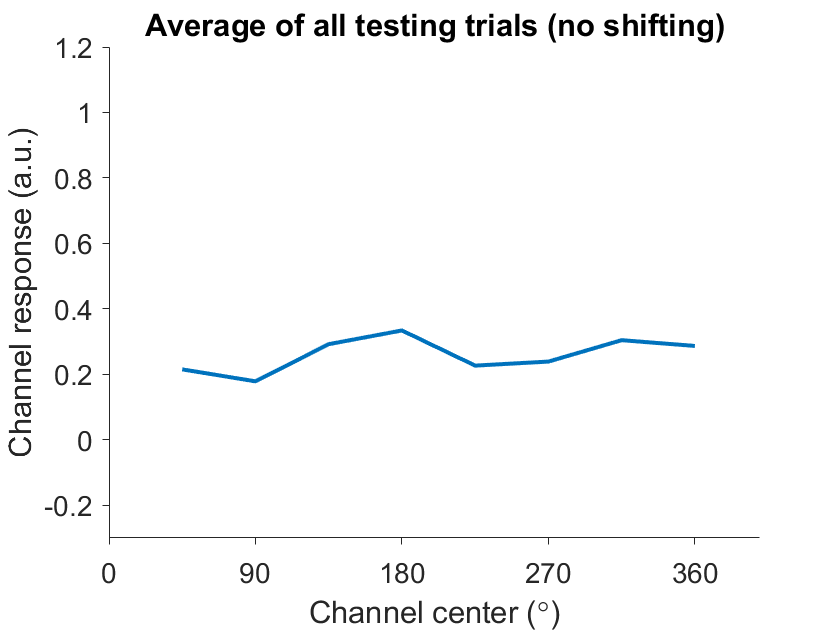

figure;
plot(chan_centers,mean(this_chan_resp,1),'-','LineWidth',2);
xlabel('Channel center (\circ)');
ylabel('Channel response (a.u.)');
title('Average of all testing trials (no shifting)');
set(gca,'XTick',0:90:360,'FontSize',14,'TickDir','out','Box','off')
ylim([-0.3 1.2]); % make our y-axis match, approximately, that above

Because we know the stimulus value on each trial, so we can manipulate our reconstructions to align all trials to the same position. 

Here, I'm going to illustrate this procedure based on the binned position information, but see the advanced tutorial for an example of how to do this using the 'raw' feature values. 

***IMPORTANT:*** the below analysis will *only* work with 8 modeled channels due to the way the data is binned. You can experiment with changing channel width, but if you change the # of channels the aligned CRFs will be nonsensical!!!!! Note that this is only an issue for this type of alignment in channel space, but full feature reconstructions are not subject to this limitation (see Advanced tutorial)

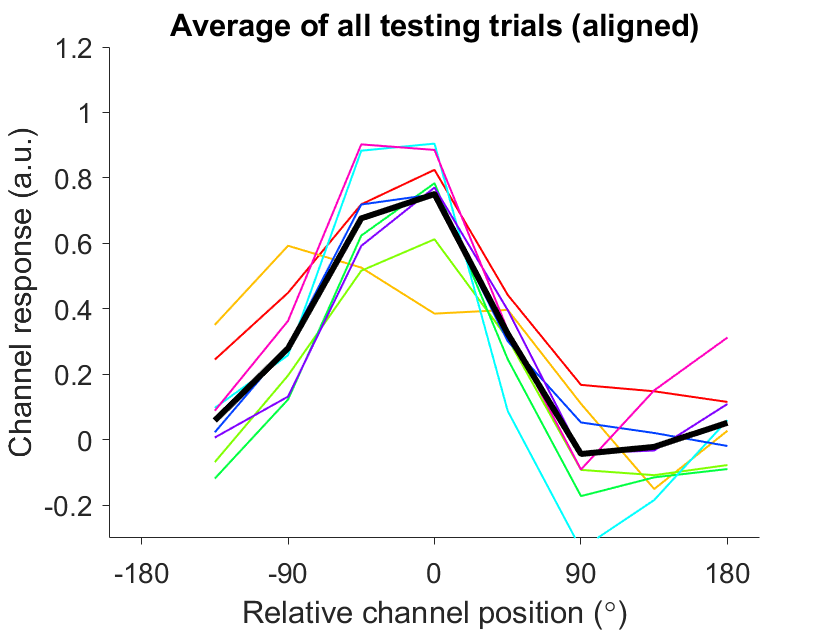

targ_pos = 180;
[~,targ_idx] = min(abs(chan_centers-targ_pos));
rel_chan_centers = chan_centers - targ_pos; % x values for plotting - relative channel position compared to aligned

% see note above: this scheme will only work when using 8 channels!!!
if n_chans == 8
    
    % create a new variable where we'll put the 'shifted' versions of channel response functions
    chan_resp_aligned = nan(size(this_chan_resp));
    
    
    % loop over all trials
    for tt = 1:size(this_chan_resp,1)
        % because we're in a circular space, we can easily just shift the values in this_chan_resp left or right so that they 'line up' across trials
        % we'll use circshift to do so. that means we need to know the direction & how much to shift by
        % + is right, - is left
        shift_by = targ_idx - this_c(tt,2); % when targ_pos is higher, we need to shift right
        shift_ang = targ_pos - mod(bin_centers(this_c(tt,2)),360);
        chan_resp_aligned(tt,:) = circshift(this_chan_resp(tt,:),shift_by);
    end
    
    % plot it - plot all trials aligned, sorted by bin in their bin color (liek above)
    % then add the mean across all trials on top
    
    figure; hold on;
    
    for pp = 1:length(pu)
        
        % pick the trials in this bin
        thisidx = this_c(:,2)==pu(pp);
        
        % plot channel responses
        plot(rel_chan_centers,mean(chan_resp_aligned(thisidx,:),1),'-','LineWidth',1,'Color',pos_colors(pp,:));
        
    end
    % plot mean
    plot(rel_chan_centers,mean(chan_resp_aligned),'k-','LineWidth',3);
    
    
    xlabel('Relative channel position (\circ)');
    ylabel('Channel response (a.u.)');
    title('Average of all testing trials (aligned)')
    ylim([-0.3 1.2])
    set(gca,'XTick',-180:90:180,'FontSize',14,'TickDir','out','Box','off')
    hold off
else
    figure;
    text(0.5,0.5,'USE 8 CHANNELS!!!!','FontSize',18,'FontWeight','bold','HorizontalAlignment','center','VerticalAlignment','middle','Color','r')
    axis off;
end

Because we know something about our *modeled feature space* (the preferred position of each information channel, because we built them in STEP 1), we can use that knowledge to manipulate that feature space - in this case, align channel response functions based on the channel position and the stimulus value on that trial. Think about it - that's *really* cool! 

The analysis framework boils down to projecting activity from a measurement space - one number for every electrode - into a simplified 'information space' - one number for each experimenter-modeled information channel. There are other cases where we can do this for simplified stimuli (e.g., averaging contralateral signals in SSVEP or alpha for stimuli presented on left/right across different trials), but it's much more complicated to imagine how you would average trials with totally random stimulus values. The IEM framework lets us do that! 

I think about the aligning & averaging step of the IEM the same way I think about ERPs: you have a complicated signal that's a combination of lots of stuff (ongoing oscillations, tiny signals of interest, blinks, etc). By cleaning the data a bit and averaging trials based on something you know - the timepoint at which a significant event in the experiment occurred - you see the consistent features of the signal locked to those events. The same is happening here - by projecting the scalp activity pattern into this information space and aligning it based on a known stimulus feature, we're getting rid of any changes in activity that aren't reliably related to changes in the stimulus feature. Sure, they'll also be projected into the activity space, but if you sample the stimulus space uniformly, the noise will likely be washed out when aligning and averaging trials from different stimulus values. 

This is, in my opinion, the key reason the IEM method is particularly powerful. I encourage you to play with parameters in these tutorials, and simulate your own datasets to test the extent to which you buy this interpretation. I can say that, in my experience, you have a lot of power to see really interesting effects of cognitive manipulations on neural representations of stimulus features.

## On to the advanced tutorial!

And there you have it! This is the essentials of performing an IEM analysis on a simplified dataset (one measurement per trial). After finishing this tutorial, you have all the skills necessary to move on to a meatier dataset - one with many samples on each trial. 